# Intro_to_Bio_ODEs.mlx

## Connection to biological systems

The IOGA concepts can be used to model biological systems. For example a differential equation could take the form of:


$$\frac{dCell}{dt}= In+Growth+Activating\; Interactions-Inhibiting\; Interactions-Natural\; Death - Out$$


where Cell represents the population of a certain cell type. Let's consider a system where tumor cells and immune cells interact in the blood stream. In this case the blood stream is the system, and the different cells types are the species whose populations we will track with differential equations.

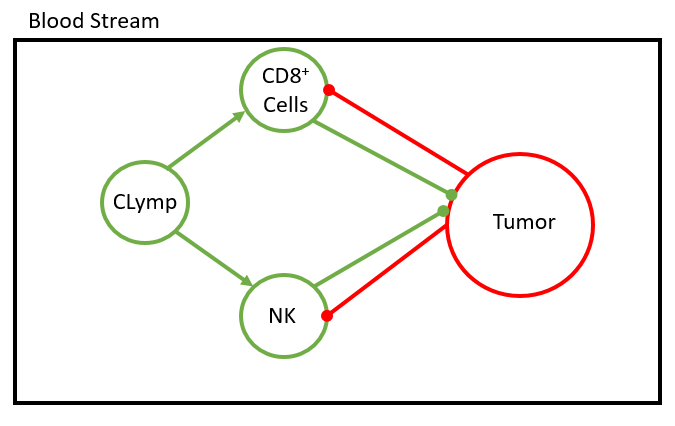

The circles are represent cells, and the lines represent interactions. The green cells are all different types of immune cells. The lines ending with a dot are inhibitory or negative relationships. Lines that end with arrows represent stimulatory or positive relationships.

Let's try to model this system. To make things easier, let's assign a letter to represent each cell species.

T=Tumor cell population

N=NK cell population

L=CD8+ T cell population

CLymp=Circulating lymphocyte cell population

Here things get a bit complex. The equations are much more complex than the lines. For example L kills T at a rate of D. D is determined by the algebraic relationship: $D=\frac{d\cdot(\frac{L}{T})^l}{s+(\frac{L}{T})^l}$. It is also important to note that these cells can be considered off if they are not at a certain threshold. For example if T>0 then the differential equation becomes 0. Let's go through building a system of equations and solving it. This will look similar to the examples in [Write_system_of_ODEs.mlx](https://github.com/ashleefv/UGResearch/blob/master/Write_system_of_ODEs.mlx).

Set up the example:

% Defining t range and intervals 
    t0 = 0;
    tf = 120; % days
    trange =linspace(t0, tf, 2501);

% We also need to set the initial conditions

 For the inital conditions set them to

    T0 = 1e6;

    N0 = 1e5;

    C0 = 6e10; 

    L0 = 100;

NOTE: 1e6 means 1x10^6. The e notation is preferred in MATLAB.

After reading through the example come back here and plug in new numbers to explore how the initial conditions alter the final solution. 

    
    T0 = 1;
    N0 = 100000;
    C0 = 60000000000;
    L0 = 100;

%Store the initial conditions in a matrix for the solver
    numerators0 = [T0; N0; L0; C0];               


Call the ODEsolver:

## Call Ode45

    [t,y]=ode45(@(t,numerators)solveODEs(t,numerators),trange,numerators0); 

In this example we only store the t and y  instead of the whole solution. Also we tell the solver what our x(t) and y(numerators) are. We do this in case we need to pass more paramerters into the solver. For example say we need to tell the ODE solver what scenario we are running. In this case the code would look like 

[t,y]=ode45(@(t,numerators)solveODEs(t,numerators,params),trange,numerators0); params would store the scenario information.

%Output vectors of numerators for each value of the denominator in the Vrange
    T = y(:,1);
    N = y(:,2);
    L = y(:,3);
    C = y(:,4);


Now let's graph the cells.

In this example we graph the y-axis on a log scale:

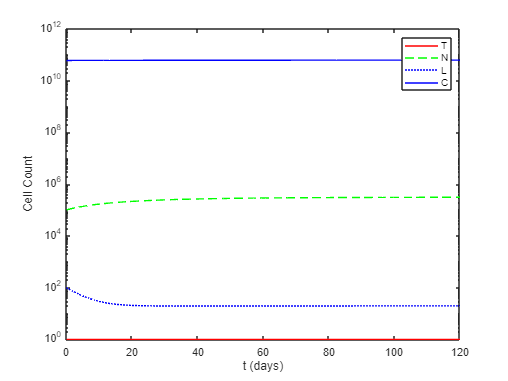

figure(1)
clf
semilogy(trange,T,'r-')
hold on
semilogy(trange,N,'g--')
semilogy(trange,L,'b:')
semilogy(trange,C,'b-')
xlim([0,tf])
ylim([10^0, 10^12])
legend('T','N','L','C')
xlabel('t (days)')
ylabel('Cell Count')
hold off

Lastly we need to write the function that defines the system of ODEs

function dsolveODEs=solveODEs(t,numerators) 
 %Set our parameters also known as rate constants
        a = 4.31e-1; % day^-1
        b = 1.02e-9; % cells^-1
        c = 6.41e-11; % cells^-1day^-1
        d = 2.34; % day^-1
        l = 2.09; % none
        s = 8.39e-2; % none
        e = 2.08e-7; % day^-1
        f = 4.12e-2; % day^-1
        g = 1.25e-2; % day^-1
        h = 2.02e7; % cell^2
        p = 3.42e-6; % cells^-1day^-1
        m = 2.04e-1; % day^-1
        j = 2.49e-2; % day^-1
        k = 3.66e7; % cell^2
        q = 1.42e-6; % cells^-1day^-1
        r1 = 1.1e-7 ;% cells^-1day^-1
        r2 = 6.5e-11 ;% cells^-1day^-1
        u = 3.00e-10 ;% cells^-2day^-1
        A = 7.5e8 ;% cellday^-1
        B = 1.20e-2 ;% day^-1

 
%  a = 4.31e-1; % day^-1
%         b = 1.02e-9; % cells^-1
%         c = 6.41e-11; % cells^-1day^-1
%         d = 2.34; % day^-1
%         l = 2.09; % none
%         s = 8.39e-2; % none
%         e = 2.08e-7; % day^-1
%         f = 4.12e-2; % day^-1
%         g = 1.25e-2; % day^-1
%         h = 2.02e7; % cell^2
%         p = 3.42e-6; % cells^-1day^-1
%         m = 2.04e-1; % day^-1
%         j = 2.49e-2; % day^-1
%         k = 3.66e7; % cell^2
%         q = 1.42e-6; % cells^-1day^-1
%         r1 = 1.1e-7 ;% cells^-1day^-1
%         r2 = 6.5e-11 ;% cells^-1day^-1
%         u = 3.00e-10 ;% cells^-2day^-1
%         A = 7.5e8 ;% cellday^-1
%         B = 1.20e-2 ;% day^-1
       
 %Assign ys to the correct species
        T = numerators(1); % Tumor Cell Population
        N = numerators(2); % Total Nk Cell Population
        L = numerators(3); % Total CD8+T Cell Population
        C = numerators(4); % Number of Lympgocytes
 %If you need any algebraic relationships type them in here
         D = d*((L/T)^l)/(s+((L/T)^l));
         
 %The ODEs 
 

Note that the equation changes if the cells are below a certain threshold

         if T > 1
             dTdt = a*T*(1-b*T)-c*N*T-D*T;
         else
             dTdt = 0;
         end
         if N >1
             dNdt = e*C-f*N+g*((T^2)/(h+T^2))*N-p*N*T;
         else
             dNdt = 0;
         end
         if L > 1                 
             dLdt = -m*L+j*(((D^2)*(T^2))/(k+((D^2)*(T^2))))*L-(q*L*T)+((r1*N)+(r2*C))*T-(u*N*(L^2));
         else
             dLdt = 0;
         end
         
         dCdt = A-B*C;
 %Set the solution matrix
         dsolveODEs = [dTdt, dNdt, dLdt, dCdt]';
end

This is a very simple example of how a biological system can be modeled as a system of differential equations. For the next step we will consider adding chemotherapy and immunotherapy like in the image below. This will allow us to explore a several senarios involving initial conditions and treatments.